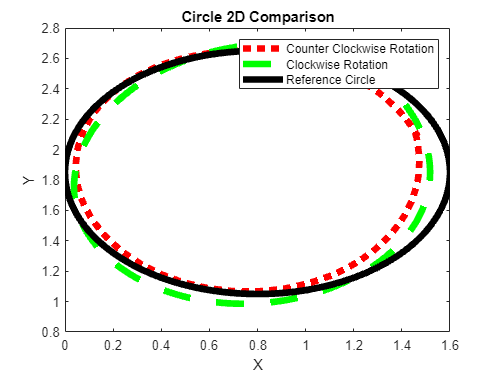

clear; % clears all var
clc; % clears command window
%data = load("third_successful.mat");
%data = load("fifth_successful.mat");
data = load("8_fking_rounds_ccw.mat");
data_cw = load("final_circle.mat");
ref = load("reference.mat");
ref_x = ref.C3(11,1:3620)-1.2;
ref_y = ref.C3(12,1:3620)-0.15;
ref_z = flip(ref.C3(13,1:3620));
size_z = size(ref_z);
z = 1.5.*ones([size(ref_z)]);

x_cw = (data_cw.final_circle(1,:));
y_cw = (data_cw.final_circle(2,:));
z_cw = (data_cw.final_circle(3,:))+0.5;

%data = load("second_successful.mat");
lower_limit = 1715;
upper_limit = 2120;
x_1 = transpose(data.test(1715:2120,1))-0.2;
y_1 = transpose(data.test(1715:2120,2))+0.2;
z_1 = transpose(data.test(1715:2120,8));

x_2 = transpose(data.test(1325:1730,1));
y_2 = transpose(data.test(1325:1730,2));
z_2 = transpose(data.test(1715:2120,8));

x_3 = transpose(data.test(1710:2115,1))-0.15;
y_3 = transpose(data.test(1710:2115,2))+0.2;
z_3 = transpose(data.test(1715:2120,8));


x_ult = (x_1 + x_2 + x_3)/3 - 1.1;
y_ult = (y_1 + y_2 + y_3)/3 + 0.8;
z_ult = (z_1 + z_2 + z_3)/3;
x_g = smoothdata(x_ult,'gaussian',10);
y_g = smoothdata(y_ult,'gaussian',10);
z_g = smoothdata(z_ult,'gaussian',10) + 0.5;

% ref comparisons


x_r_cw = zeros(1,size(x_cw,2)); % 301
y_r_cw = zeros(1,size(x_cw,2));
z_r_cw = zeros(1,size(x_cw,2));

x_r_ccw = zeros(1,size(x_g,2)); % 406
y_r_ccw = zeros(1,size(x_g,2));
z_r_ccw = zeros(1,size(x_g,2));

x_error_cw = zeros(1,size(x_cw,2)); % 301
y_error_cw = zeros(1,size(x_cw,2));
z_error_cw = zeros(1,size(x_cw,2));

x_error_ccw = zeros(1,size(x_g,2)); % 406
y_error_ccw = zeros(1,size(x_g,2));
z_error_ccw = zeros(1,size(x_g,2));

x_vel_cw = zeros(1,size(x_cw,2)-1); % 301
y_vel_cw = zeros(1,size(x_cw,2)-1);
z_vel_cw = zeros(1,size(x_cw,2)-1);

x_vel_ccw = zeros(1,size(x_g,2)-1); % 406
y_vel_ccw = zeros(1,size(x_g,2)-1);
z_vel_ccw = zeros(1,size(x_g,2)-1);



for i = 1:size(x_cw,2)
    c = i*12;
    x_r_cw(1,i) = ref_x(1,c);
    y_r_cw(1,i) = ref_y(1,c);
    z_r_cw(1,i) = z(1,c);
end

for i = 1:size(x_g,2)
    c = i*8;
    x_r_ccw(1,i) = ref_x(1,c);
    y_r_ccw(1,i) = ref_y(1,c);
    z_r_ccw(1,i) = z(1,c);
end

for i = 1:size(x_cw,2)
    x_error_cw(1,i) = abs(x_r_cw(1,i)-x_cw(1,i));
    y_error_cw(1,i) = abs(y_r_cw(1,i)-y_cw(1,i));
    z_error_cw(1,i) = abs(z_r_cw(1,i)-z_cw(1,i));
end

for i = 1:size(x_cw,2)-1
    x_vel_cw(1,i) = abs(x_cw(1,i+1)-x_cw(1,i))/0.01;
    y_vel_cw(1,i) = abs(y_cw(1,i+1)-y_cw(1,i))/0.01;
    z_vel_cw(1,i) = abs(z_cw(1,i+1)-z_cw(1,i))/0.01;
end

for i = 1:size(x_g,2)
    x_error_ccw(1,i) = abs(x_r_ccw(1,i)-x_g(1,i));
    y_error_ccw(1,i) = abs(y_r_ccw(1,i)-y_g(1,i));
    z_error_ccw(1,i) = abs(z_r_ccw(1,i)-z_g(1,i));
end

for i = 1:size(x_g,2)-1
    x_vel_ccw(1,i) = abs(x_g(1,i+1)-x_g(1,i))/0.01;
    y_vel_ccw(1,i) = abs(y_g(1,i+1)-y_g(1,i))/0.01;
    z_vel_ccw(1,i) = abs(z_g(1,i+1)-z_g(1,i))/0.01;
end

% bod_rates = transpose(data.test(1:limit,3)); 
% motor = transpose(data.test(1:limit,4));
x_error_cw = smoothdata(x_error_cw,'gaussian',500);
y_error_cw = smoothdata(y_error_cw,'gaussian',350);
z_error_cw = smoothdata(z_error_cw,'gaussian',10);

x_error_ccw = smoothdata(x_error_ccw,'gaussian',500);
y_error_ccw = smoothdata(y_error_ccw,'gaussian',500);
z_error_ccw = smoothdata(z_error_ccw,'gaussian',10);

x_vel_ccw = smoothdata(x_vel_ccw,'gaussian',300);
y_vel_ccw = smoothdata(y_vel_ccw,'gaussian',350);
z_vel_ccw = smoothdata(z_vel_ccw,'gaussian',300);

x_vel_cw = smoothdata(x_vel_cw,'gaussian',300);
y_vel_cw = smoothdata(y_vel_cw,'gaussian',350);
z_vel_cw = smoothdata(z_vel_cw,'gaussian',300);
% bod_rates_g = smoothdata(bod_rates,'gaussian',1000);
% heading = rad2deg(transpose(data.test(1:limit,5)));
% pitch = rad2deg(transpose(data.test(1:limit,6)));
% pitch = smoothdata(pitch,'gaussian',1000);
% 
% 
% 
% 
% 
% 
% plot(time,smoothedbod_roll,'Color','b','linewidth',5)
figure(1)
% plot(ref_x,ref_y,'Color','b','linewidth',5)
% xlabel('X-Pose Ref')
% ylabel('Y-Pose Ref')
% title('Ref Pose')
% axis equal


% plot(x_1,y_1,'Color','b','linewidth',5)
% xlabel('X-Pose')
% ylabel('Y-Pose')
% title('Pose ')
% 
% hold on
% plot(x_2,y_2,'Color','r','linewidth',5)
% xlabel('X-Pose')
% ylabel('Y-Pose')
% 
% 
% plot(x_3,y_3,'Color','g','linewidth',5)
% xlabel('X-Pose')
% ylabel('Y-Pose')
% 
% 
% 
% 
% % plot(x_g,y_g,'Color','r','linewidth',5)
% % xlabel('X-Pose')
% % ylabel('Y-Pose')
% % title('Pose w gaussian')
% % % title('comparison')
% 
% 
% hold off 

% plot3(ref_x, ref_y, ref_z, 'Color','r','LineWidth',2);
% xlabel('X-Pose')
% ylabel('Y-Pose')
% zlabel('Z-Pose')

% plot(x_ult,y_ult,'Color','g','linewidth',5)
% xlabel('X-Pose')
% ylabel('Y-Pose')

plot(x_g,y_g,'Color','red','lineStyle',':','linewidth',5);

% % title('comparison')
hold on
plot(x_cw, y_cw, 'Color','green','lineStyle','--','LineWidth',5);

plot(x_r_ccw, y_r_ccw, 'Color','black','LineWidth',5);


xlabel('X')
ylabel('Y')
title('Circle 2D Comparison')
legend('Counter Clockwise Rotation','Clockwise Rotation','Reference Circle')
hold off 

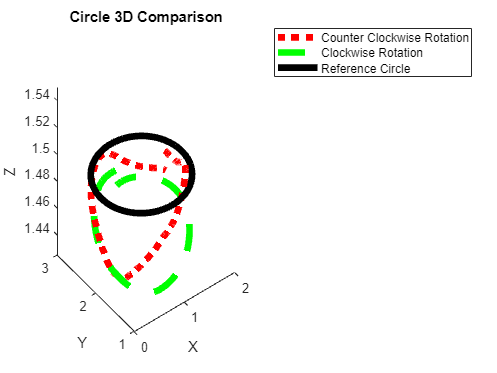



plot3(x_g,y_g,z_g,'Color','red','lineStyle',':','linewidth',5)

% % title('comparison')
hold on

plot3(x_cw,y_cw,z_cw,'Color','green','lineStyle','--','LineWidth',5);
plot3(ref_x,ref_y,z,'Color','black','LineWidth',5);
xlabel('X')
ylabel('Y')
zlabel('Z')
title('Circle 3D Comparison')
legend('Counter Clockwise Rotation','Clockwise Rotation','Reference Circle')
zlim([1.425 1.55]);
hold off 


% t = tiledlayout(1,2);
% nexttile
% plot(1:size(x_cw,2),x_error_cw,'Color','red','lineStyle',':','linewidth',5)
% hold on
% plot(1:size(x_cw,2),y_error_cw,'Color','green','lineStyle','--','LineWidth',5)
% plot(1:size(x_cw,2),z_error_cw,'Color','black','lineStyle','-.','LineWidth',5)
% xlim([0 300]);
% xlabel('Time Sequence')
% ylabel('Position Error')
% zlabel('Z')
% title('Clockwise Rotation - Blue Side Up')
% legend('X','Y','Z')
% hold off
% nexttile
% plot(1:size(x_g,2),x_error_ccw,'Color','red','lineStyle',':','linewidth',5)
% hold on
% plot(1:size(x_g,2),y_error_ccw,'Color','green','lineStyle','--','LineWidth',5)
% plot(1:size(x_g,2),z_error_ccw,'Color','black','lineStyle','-.','LineWidth',5)
% xlim([0 300]);
% xlabel('Time Sequence')
% ylabel('Position Error')
% zlabel('Z')
% title('Counter Clockwise Rotation - Red Side Up')
% legend('X','Y','Z')
% hold off

t = tiledlayout(1,2);

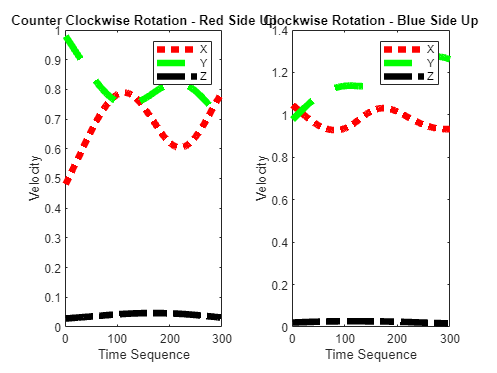

nexttile
plot(1:size(x_g,2)-1,x_vel_ccw,'Color','red','lineStyle',':','linewidth',5)
hold on
plot(1:size(x_g,2)-1,y_vel_ccw,'Color','green','lineStyle','--','LineWidth',5)
plot(1:size(x_g,2)-1,z_vel_ccw,'Color','black','lineStyle','-.','LineWidth',5)
xlim([0 300]);
xlabel('Time Sequence')
ylabel('Velocity')
zlabel('Z')
title('Counter Clockwise Rotation - Red Side Up')
legend('X','Y','Z')
hold off

nexttile
plot(1:size(x_cw,2)-1,x_vel_cw,'Color','red','lineStyle',':','linewidth',5)
hold on
plot(1:size(x_cw,2)-1,y_vel_cw,'Color','green','lineStyle','--','LineWidth',5)
plot(1:size(x_cw,2)-1,z_vel_cw,'Color','black','lineStyle','-.','LineWidth',5)
xlabel('Time Sequence')
ylabel('Velocity')
zlabel('Z')
title('Clockwise Rotation - Blue Side Up')
legend('X','Y','Z')
hold off


% xlabel('Time')
% ylabel('Bod Rates')
% title('Rates vs index')
% plot(1:limit,motor,'Color','r','linewidth',5)
% xlabel('Time')
% ylabel('Motor')
% title('Motor vs index')
% plot(1:limit,heading,'Color','b','linewidth',5)
% xlabel('Time')
% ylabel('heading')
% title('Heading vs index')
% plot(1:limit,pitch,'Color','r','linewidth',5)
% xlabel('Time')
% ylabel('pitch')
% title('Pitch vs index')